# Lab session IV:

## Intro:

On this Laboratory session we are going to work with the different attitude representations seen in class. 

- Exercise 1: 1 point. To be delivered before the end of the session.

- Exercise 2: 3 points

- Exercise 3: 3 points

- Exercise 4: 3 points

**Lab rules:**

- Always respect the delivery dates

- Use the templates when provided and DO NOT MODIFY THE FILE NAMES OR THE FUNCTION NAMES

- Verify that your code works before submit

- Always upload the files in a .zip with the name structure:  * Surname_Name.zip*

- Cheating is not allowed and will be firmly punished with a final mark of 0

This assignment is due to 28/11/2018.

# Exercise 1:

The point p has coordinates

p_A = [3, 4]';

on a frame {A}, and coordinates

p_B = [-2.5, 0.5]';

on a frame {B}.

It is known that the angle between $x$-axis of frame {A} and the$y$ axes of the frame {B} is 30 deg counterclockwise.

##  1.1 Which are the coordinates of the origin of A seen from B?

% p_B = BRA * p_A + BdB_A
BRA = [cosd(-60) sind(-60); -sind(-60) cosd(-60)]

BRA =     0.5000   -0.8660
    0.8660    0.5000


p_A_Rot = BRA * p_A

p_A_Rot =    -1.9641
    4.5981


BdB_A = p_B - p_A_Rot

BdB_A =    -0.5359
   -4.0981


##  1.2 Which are the coordinates of the origin of B seen from A?

% p_A = ARB * p_B + AdA_B
ARB = BRA'

ARB =     0.5000    0.8660
   -0.8660    0.5000


p_B_Rot = ARB * p_B

p_B_Rot =    -0.8170
    2.4151


AdA_B = p_A - p_B_Rot

AdA_B =     3.8170
    1.5849


##  1.3 Which are the coordinates of a point q expressed in A if 

q_B = [3,1]';
q_A = ARB * q_B + AdA_B

q_A =     6.1830
   -0.5131


# Exercise 2:

 Let {A}, {B} and {C}, be 3 different reference frames. From them we know that:

- The origin of B with respect A is

AoB = [3,1,-2]';

- The origin of C with respect B is

BoC = [-3, 1,-2]';

- The three frames has different orientations in space. In fact:  

- The set of Euler angles stored in $\eta$ as $\eta = (\psi,\theta,\phi)$

eta = [25;145;30]; % Expressed in degrees

                 represent 3 consecutive rotations about z, y, and x respectively that allows to transform vectors from {A} to {B}

- The quaternion

q = 1/7*[-sqrt(3)*3.5;3;-1;-1.5]

q =    -0.8660
    0.4286
   -0.1429
   -0.2143


                 allows to express in {B} a vector defined in {C}, if {C} and {B} had the same origin

Let in addition v1 and v2 to be points which coordinates are known in  {C}.

v1_C = [0;2;0];
v2_C = [0;2;5];

With the information provided above determine:

##  2.1.1 The affine** expression** that allows to relate a vector originally given in {C} to {B}. Note that no calculations have to be provided here, only the expression which is not a matrix.

In the first place, we need to make sure that the quaternion is a unit quaternion, so we are able to perform a rotation. Secondly, it is important to remember that the vector won't have initially the same origin, because the frames are in different positions. Solution: displace vector with the distance between the two frames. Thirdly, to rotate the vector originally given in {C}, we need to convert it into a pure quaternion, like this: v_displaced_quaternion = [0; v_displaced + BoC]. In the fourth place, with this affine expression we should be able to perform this affine transformation using quaternions.

## 2.1.2 Implement a function called rotVbyq that provided a vector and a quaternion rotates the vector using quaternion multiplications. Test it and comment why do you think it is well implemented.

vector_rotated = rotVbyq(v2_C - v1_C + BoC, q)

vector_rotated =    -0.6663
    0.5059
    0.5478


##  2.2 The affine matrix that allows to express a vector originally given in {C} to {A}.

% In this exercise, we will need to access the different values of eta. Keep in mind that eta goes from z to x, in this order.
angle_x = eta(3);
angle_y = eta(2);
angle_z = eta(1);

% the minus.....
R_x = [1 0 0; 0 cosd(angle_x) -sind(angle_x); 0 sind(angle_x) cosd(angle_x)];
R_y = [cosd(angle_y) 0 sind(angle_y); 0 1 0; -sind(angle_y) 0 cosd(angle_y)];
R_z = [cosd(angle_z) -sind(angle_z) 0; sind(angle_z) cosd(angle_z) 0; 0 0 1];

ARB = R_z * R_y * R_x % transpose maybe...

ARB =    -0.7424   -0.1061    0.6615
   -0.3462    0.9061   -0.2432
   -0.5736   -0.4096   -0.7094



% Now we have ARB. Let's get BRC with the quaternion given.
% p is the conjugate of q. To find Q_L and Q_R, we simply follow the steps of the product of two quaternions (that's the method used here).
p = [q(1); -q(2); -q(3); -q(4)];
Q_L = [q(1) -q(2) -q(3) -q(4); q(2) q(1) -q(4) q(3); q(3) q(4) q(1) -q(2); q(4) -q(3) q(2) q(1)];
Q_R = [p(1) -p(2) -p(3) -p(4); p(2) p(1) p(4) -p(3); p(3) -p(4) p(1) p(2); p(4) p(3) -p(2) p(1)];
Q_LR = Q_L * Q_R;
% Q_L * Q_R has dimensions [4, 4], so we want the 3x3 part of the bottom-right of the matrix.
BRC = Q_LR(2:4, 2:4)

BRC =     0.8673   -0.4936    0.0638
    0.2487    0.5408    0.8035
   -0.4311   -0.6811    0.5918



% Finally, we can have the desired rotation matrix {C} -> {A}
ARC = ARB * BRC

ARC =    -0.9555   -0.1415    0.2589
    0.0299    0.8266    0.5620
   -0.2935    0.5448   -0.7855


## 2.3 The vectors v1_C and v2_C forms a segment. Make a 3d plot (plot3() in matlab), representing how the segment is seen on {A} in red, on {B} in blue and on {C} in green.

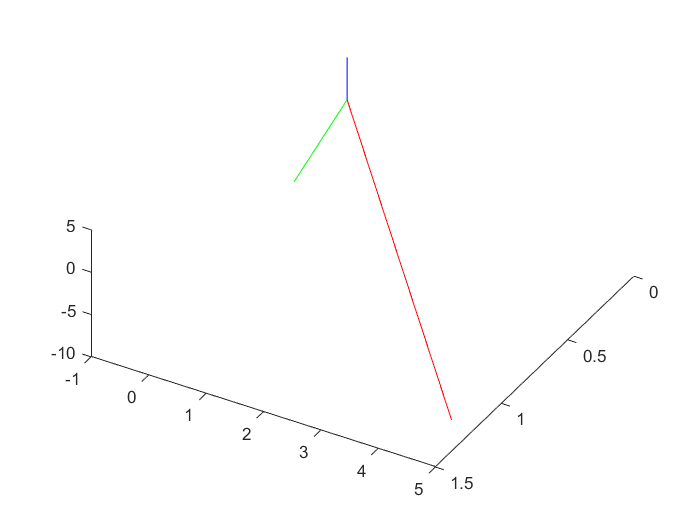

% Points?
v_C = v2_C - v1_C;

AoC = AoB + BoC;
v_A = ARC * v_C + AoC;
v_B = ARB * v_C + BoC;

origin_xyz = 0;
plot3([origin_xyz, v_A(1)], [origin_xyz, v_A(2)], [origin_xyz, v_A(3)], 'Color', [255, 0, 0] / 255);
hold on
plot3([origin_xyz, v_B(1)], [origin_xyz, v_B(2)], [origin_xyz, v_B(3)], 'Color', [0, 255, 0] / 255);
plot3([origin_xyz, v_C(1)], [origin_xyz, v_C(2)], [origin_xyz, v_C(3)], 'Color', [0, 0, 255] / 255);
hold off

% rotate3d on;
view(120, 60)

# Exercise 3:

The points described by the columns of the matrix A 

A = load('AEx3.mat');
A = A.A;

are points contained into a circle, and they are defined in a world frame W.

A camera is situated at point

wc = [1; 6; 1];

 defined in the world frame. Moreover the orientation of this camera frame is achieved by rotating the world frame 90 degs about its y axis followed by -20 degrees about the resulting z axis.

If the camera has a focal length of 1/34 m:

##  3.1 Make a plot with the view of the points of the circle projected into the camera plane.

% First of all, we need to set the camera orientation correctly, just as the statement says. Only y-z axis though.
R_y = [cosd(90) 0 sind(90); 0 1 0; -sind(90) 0 cosd(90)]

R_y =      0     0     1
     0     1     0
    -1     0     0


R_z = [cosd(-20) -sind(-20) 0; sind(-20) cosd(-20) 0; 0 0 1]

R_z =     0.9397    0.3420         0
   -0.3420    0.9397         0
         0         0    1.0000


Rotation_Matrix = R_z * R_y

Rotation_Matrix =          0    0.3420    0.9397
         0    0.9397   -0.3420
   -1.0000         0         0


% Now we need the affine matrix to put in the cameraproj.m function.
CRW = Rotation_Matrix

CRW =          0    0.3420    0.9397
         0    0.9397   -0.3420
   -1.0000         0         0


CdCW = -CRW * wc

CdCW =    -2.9918
   -5.2961
    1.0000


CAW = [CRW CdCW; [0 0 0] 1]

CAW =          0    0.3420    0.9397   -2.9918
         0    0.9397   -0.3420   -5.2961
   -1.0000         0         0    1.0000
         0         0         0    1.0000



% The points given in A form a circle together. We need to view them from the camera.
focal_length = 1/34;
[A_height, A_width] = size(A);
cam_stored_points = zeros(3, A_width);
camera_points_2d = zeros(2, A_width);

for i = 1 : A_width
    cam_stored_points(:, i) = -CRW * A(:, i);
end

for i = 1 : A_width
   camera_points_2d(:, i) = cameraproj(CAW, focal_length, cam_stored_points(:, i));
end

for i = 1 : A_width
   plot3([camera_points_2d(1, i) camera_points_2d(1, i)], [camera_points_2d(2, i) camera_points_2d(2, i)], [0, 0], 'o', 'Color', [255, 0, 0] / 255);
   hold on
end

##  3.2 Make also a 3D plot where all the scene is drawn in the world coordinates. The scene must contain the 2 reference frames (2 orthogonal sets of vectors) and the circle points. 

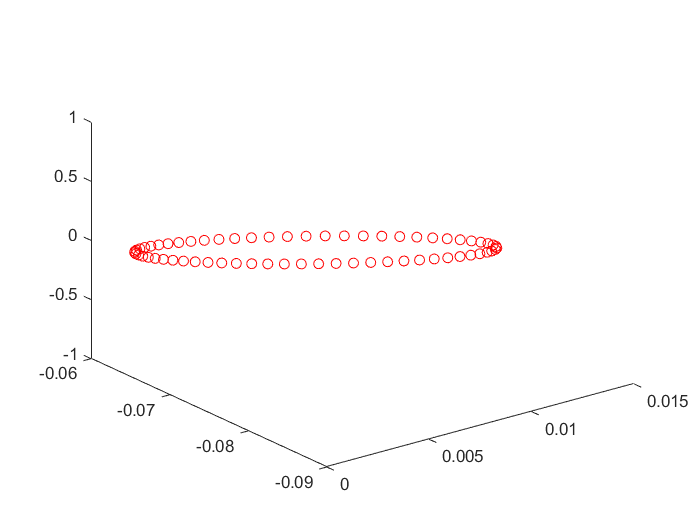

hold off

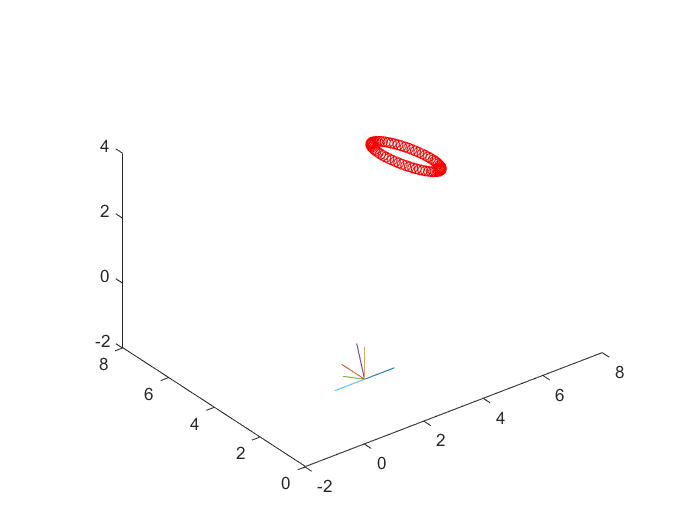

% FWorld axis
i_axis = [0 1; 0 0; 0 0];
j_axis = [0 0; 0 1; 0 0];
k_axis = [0 0; 0 0; 0 1];
plot3(i_axis(1, :),i_axis(2, :),i_axis(3, :))
hold on
plot3(j_axis(1, :),j_axis(2, :),j_axis(3, :))
plot3(k_axis(1, :),k_axis(2, :),k_axis(3, :))

% FCamera axis
% Note: 4x2 multiplication. Remember that on every axis we store its origin and destination. Of course, they are unit.
i_axis_camera = CAW * [i_axis; 1 1];
j_axis_camera = CAW * [j_axis; 1 1];
k_axis_camera = CAW * [k_axis; 1 1];
plot3(i_axis_camera(1, 1:2), i_axis_camera(2, 1:2), i_axis_camera(3, 1:2))
plot3(j_axis_camera(1, 1:2), j_axis_camera(2, 1:2), j_axis_camera(3, 1:2))
plot3(k_axis_camera(1, 1:2), k_axis_camera(2, 1:2), k_axis_camera(3, 1:2))

% Remember that points are plotted from FWorld, so we access them from the given A.
for i = 1 : A_width
    plot3(A(1, i), A(2, i), A(3, i), 'o', 'Color', [255, 0, 0] / 255);
    hold on
end
daspect([1 1 1]); % Maintain [1 1 1] aspect in orded to visualize things a LOT better.
hold off

You can use the provided function cameraproj.

# Exercise 4:

The columns of the next matrix, represents the coordinates od 4 points defined in a world frame.

A = load('AEx4.mat');
A = A.A;

From this 4 points, two segments are defined. The segment one, goes from the point defined by the first column to the point defined by the second column. The second segment is defined by the other two points.

 A camera frame is seeing the scene. The origin of the world frame seen from the camera frame is given by the vector

wc = [4.665;3.735;-0.5395];

And the orientation of the camera frame is obtained after rotating the world frame -150 degs about the direction

u = [0.01;-.2;1];

With the data provided determine:

## 4.1 The minimum angle that both segments forms (hint, they intersect)

## 4.2 The angle that both segments forms in the image plane

## 4.3 Deliver a 3D representation of the scene with all the coordinates refered to the world frame

## 4.4 Deliver the same 3D scene representations but with all the coordinates refered to the camera frame